# Numerical Analysis Project 2

Nathaniel Valla

format long

### Function used:

    newtons_div_dff(x_i,y_i): Takes two arrays of the same size and uses divided differences to find largangian polnoimal

    bezier_curves(x_i,y_i,y_d):Takes in two arrays of function values and in two arrays of derivatives. 

    derivatives(h,y_i): Takes in two arrays of function values and in two arrays of derivatives

### Test cases:

        1. cos(x-0.2)

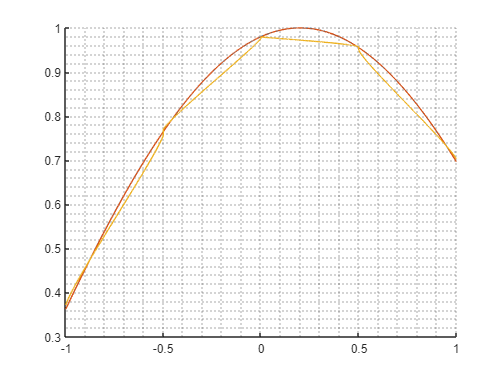

n = linspace(-1,1,5);
t = linspace(-1,1,10000);
h = n(2)-(1);

y_cos_shift = cos(n-0.2);
lag_cos_shift = newtons_div_dff(n,y_cos_shift,t);
y_cos_diff = derivatives(h,y_cos_shift);
bezier_cos_shif = bezier_curves(n,y_cos_shift,y_cos_diff,t,h);

figure
hold on 
plot(t,cos(t-0.2))
plot(t,lag_cos_shift)
plot(t,bezier_cos_shif)
grid minor
hold off

        2. cos(x-0.2)

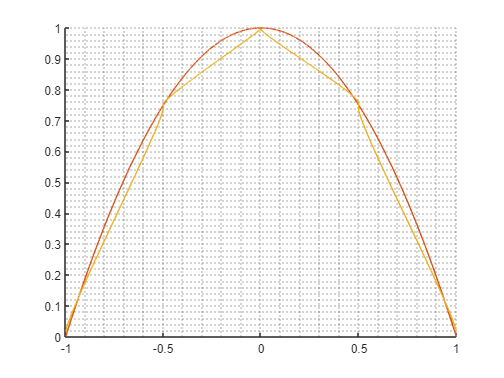

n = linspace(-1,1,5);
t = linspace(-1,1,10000);
h = n(2)-(1);

y_parabola = 1-n.^2;
lag_parabola = newtons_div_dff(n,y_parabola,t);
y_para_diff = derivatives(h,y_parabola);
bezier_para = bezier_curves(n,y_parabola,y_para_diff,t,h);

figure
hold on 
plot(t,1-t.^2)
plot(t,lag_parabola)
plot(t,bezier_para)
grid minor
hold off

        3. sqrt(5-x^2)

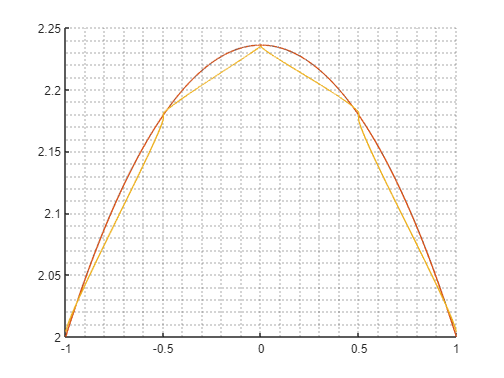

n = linspace(-1,1,5);
t = linspace(-1,1,10000);
h = n(2)-(1);

y_sqrt = sqrt(5-n.^2);
lag_sqrt = newtons_div_dff(n,y_sqrt,t);
y_sqrt_diff = derivatives(h,y_sqrt);
bezier_sqrt = bezier_curves(n,y_sqrt,y_sqrt_diff,t,h);

figure
hold on 
plot(t,sqrt(5-t.^2))
plot(t,lag_sqrt)
plot(t,bezier_sqrt)
grid minor
hold off